weight_torso = 700;
additional_weight = 1000;
%with 300kg more we reach the 200Nm in the motor

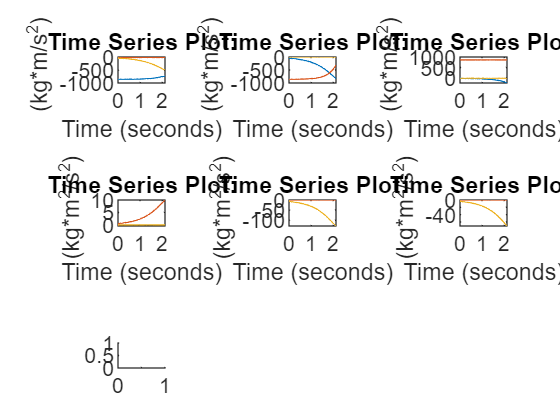

tiledlayout(3,3)
nexttile
plot(out.force_hip)
nexttile
plot(out.force_knee)
nexttile
plot(out.force_ankle)
nexttile
plot(out.torque_hip)
nexttile
plot(out.torque_knee)
nexttile
plot(out.torque_ankle)
nexttile


%torsional stiffness k = M/theta
k_knee = out.torque_knee.Data(:,3)./eulerd(quaternion(out.rotation_angle_knee.Data),'XYZ','frame');

'quaternion' requires one of the following:
  Automated Driving Toolbox
  Navigation Toolbox
  Radar Toolbox
  Robotics System Toolbox
  Sensor Fusion and Tracking Toolbox
  UAV Toolbox

k_ankle = out.torque_ankle.Data(:,3)./out.rotation_angle_ankle.Data;

plot(k_knee)
nexttile
plot(k_ankle)
